# PARTE 1: Laboratorio 2 MyS

- Autores: Vanina Correa y John Serrano

Se busca crear las funciones bam y mab para encontrar el modelo de estado matricial y la función de transferencia de un sistema. Luego, se compara el resultado obtenido con la función de transferencia obtenida mediante la función feedback de Matlab y se grafica la respuesta frente al escalón.

% Se limpian las variables guardadas en el Workspace.
clearvars;

% Define valores para probar las funciones bam y mab.
a = 1;
b = 1;
c = 1;
d = 1;
e = 1;
f = 1;

% Calcula modelo matricial utilizando la función bam.
[A,B,C,D] = bam(1,1,1,1,1,1)

A =      1    -1
     1     1


B =      1
     0


C =      1     0


D = 0


% Calcula la función de transferencia utilizando la función mab.
H_mab = mab(A,B,C,D)

H_mab =
 
      s - 1
  -------------
  s^2 - 2 s + 2
 
Continuous-time transfer function.
Model Properties



% Se define el modelo para las funciones de transferencia.
s = tf('s');

% Funciones de transferencia de los sistemas del diagrama de bloque.
H1 = a/(b*s - c);
H2 = d/(e*s - f);

% Calcula la función de transferencia utilizando funciones de Matlab para
% verificar el resultado anterior 
H_feedback = feedback(H1, H2)

H_feedback =
 
      s - 1
  -------------
  s^2 - 2 s + 2
 
Continuous-time transfer function.
Model Properties


Como se puede observar, las funciones de transferencia calculadas con mab y feedback coinciden, por lo que el procedimiento es correcto. Adicionalmente, se grafica la respuesta de ambos sistemas frente a un escalón.

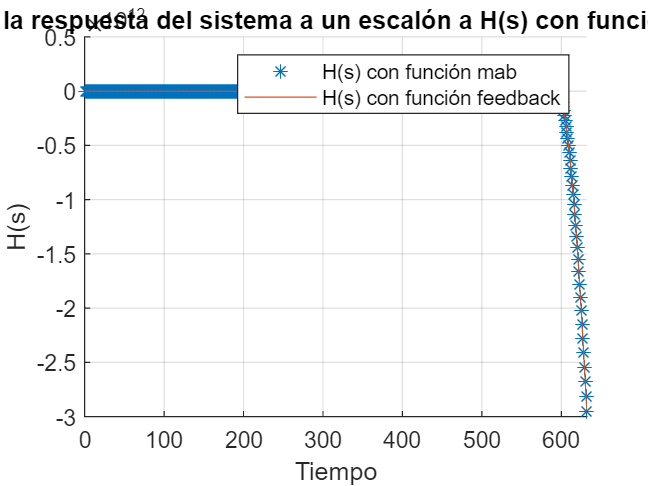

% Grafica la respuesta del sistema a un escalón.
figure;
title("Comparación de la respuesta del sistema a un escalón a H(s) con función mab y feedback")
xlabel("Tiempo")
ylabel("H(s)")
grid("on");
hold on
plot(step(H_mab), "*");
plot(step(H_feedback), "-");
legend("H(s) con función mab", "H(s) con función feedback")